% Settings
clear;

## Results

c = [0.397 0 130];
alpha = [1.8e-6 1 1400]';
m = 1633;

T = 0.1;

cycles = ["us_ftp75","us_us06","eu_nedc","wltp_3b","cadc_urban","cadc_rural","cadc_mw150"]; %,"cadc_mw150"];
d = table();
for Cycle = cycles
    ct = eval("elvio_cycle_"+Cycle+"()");
    [v,t,a] = elvio_resample(ct,T);

    dur = t(end);
    dis = sum(v)*T;

    v0 = mean(v);

    mup = [mean(v.^(6:-1:0)) mean((v.*a).^2)];
    mui = [mean((v-v0).^(6:-1:0)) mean((v.*a).^2)];

    [kp,kp_av] = stat_kp(c,alpha,m);
    [ki,k_av] = stat_k(kp,kp_av,v0);
    kp = [kp;kp_av]';
    ki = [ki;kp_av]';

    kmup = kp.*mup;
    kmui = ki.*mui;

    t1 = table(Cycle, dur, dis, v0, mup, mui, kp, ki, kmup, kmui);
    d = [d;t1];
end

d

d = 7×10 table
       Cycle        dur      dis       v0         mup           mui            kp            ki           kmup          kmui   
    ____________    ____    _____    ______    __________    __________    __________    __________    __________    __________

    "us_ftp75"      1877    17769    9.4664    1×8 double    1×8 double    1×8 double    1×8 double    1×8 double    1×8 double
    "us_us06"        600    12888    21.476    1×8 double    1×8 double    1×8 double    1×8 double    1×8 double    1×8 double
    "eu_nedc"       1100    11012     10.01    1×8 double    1×8 double    1×8 double    1×8 double    1×8 double    1×8 double
    

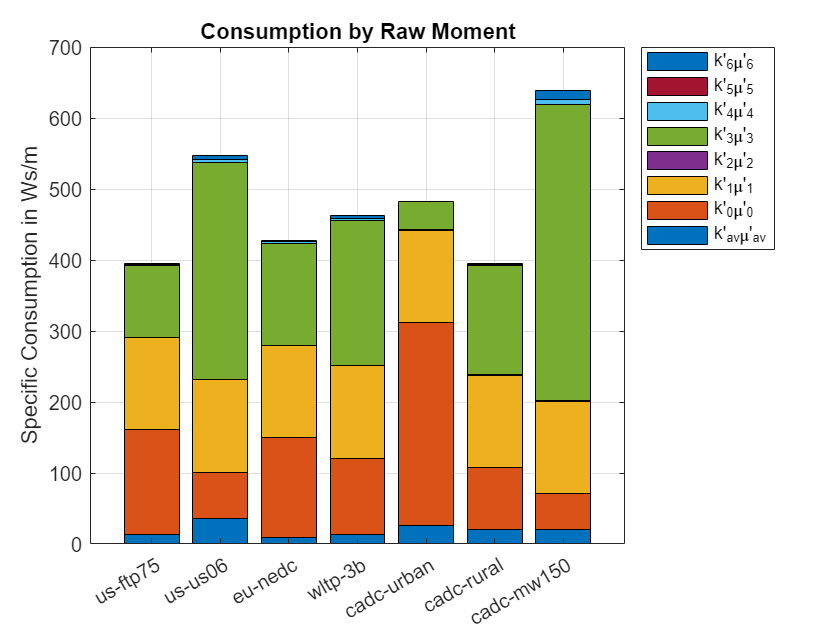

ks = ["k'_6\mu'_6","k'_5\mu'_5","k'_4\mu'_4","k'_3\mu'_3","k'_2\mu'_2","k'_1\mu'_1","k'_0\mu'_0","k'_{av}\mu'_{av}"];

cat2 = strrep(cycles,"_","-");
cat = categorical(cat2);
cat = reordercats(cat,cat2);
h = bar(cat,d.kmup(:,end:-1:1)./(d.v0),"stacked");
legend(h(end:-1:1),ks,"Location","northeastoutside");
ylabel("Specific Consumption in Ws/m");
title("Consumption by Raw Moment");
grid;

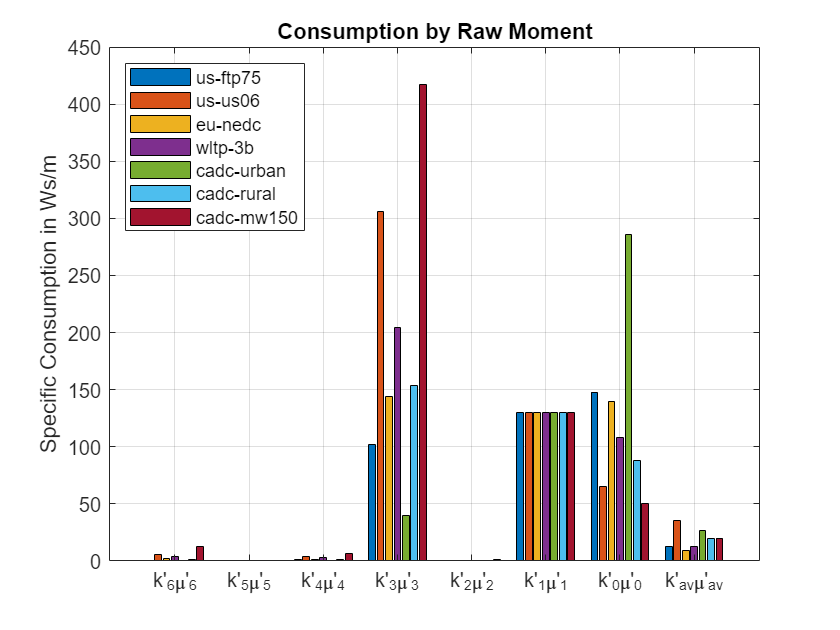

cat = categorical(ks);
cat = reordercats(cat,ks);
%bar(cat,d.kmup(:,end:-1:1)./(d.v0),"stacked");
bar(cat,(d.kmup(:,:)./(d.v0))');
legend(strrep(cycles,"_","-"),"Location","northwest");
ylabel("Specific Consumption in Ws/m");
title("Consumption by Raw Moment");
grid;

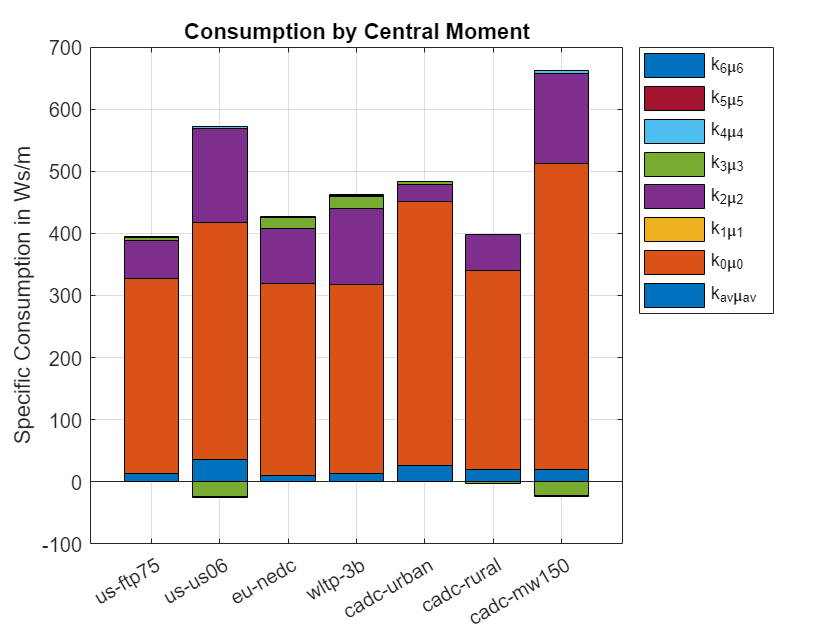

ks = strrep(ks,"'","");
cat = categorical(cat2);
cat = reordercats(cat,cat2);
h = bar(cat,d.kmui(:,end:-1:1)./(d.v0),"stacked");
legend(h(end:-1:1),ks,"Location","northeastoutside");
ylabel("Specific Consumption in Ws/m");
title("Consumption by Central Moment");
grid;

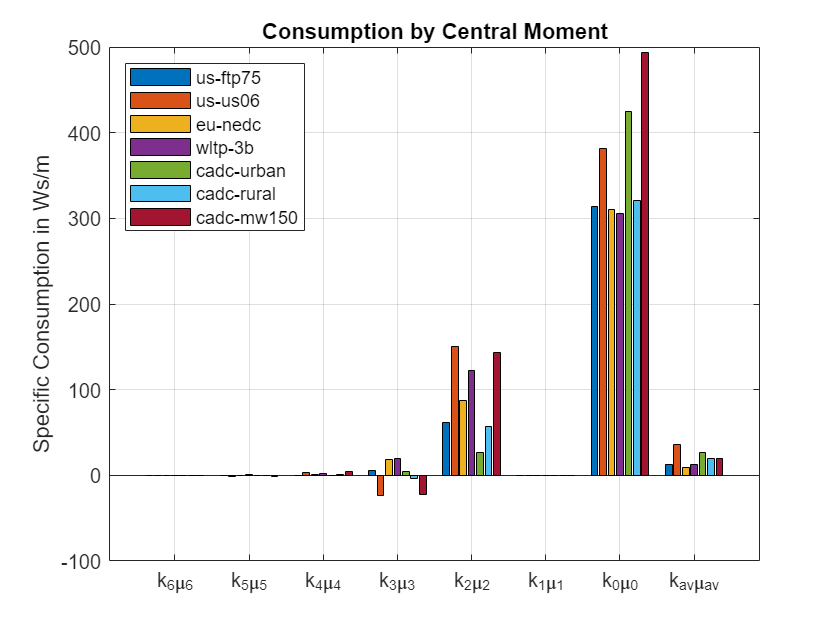

cat = categorical(ks);
cat = reordercats(cat,ks);
%bar(cat,d.kmup(:,end:-1:1)./(d.v0),"stacked");
bar(cat,(d.kmui(:,:)./(d.v0))');
legend(strrep(cycles,"_","-"),"Location","northwest");
ylabel("Specific Consumption in Ws/m");
title("Consumption by Central Moment");
grid;